# FF_VFI_AZ_VEC Savings Vectorized Grid Examples

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**Dynamic Asset**](https://fanwangecon.github.io/CodeDynaAsset/)** Repositories**

This is the example vignette for function: [**ff_vfi_az_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_vec.m) from the [**MEconTools Package**](https://fanwangecon.github.io/MEconTools/)**. **This function solves the dynamic programming problem for a (a,z) model. Households can save a, and face AR(1) shock z. The problem is solved over the infinite horizon. 

This is the **vectorized** code, its speed is much faster than the looped code. The function is designed to have small memory footprint and requires low computing resources, yet is fast.

The code uses **common grid**, with the same state space and choice space grids. [**ff_vfi_az_bisec_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_bisec_vec.m) from the [**MEconTools Package**](https://fanwangecon.github.io/MEconTools/) solves the same problem but using continuous exact percentage asset choices, which is more precise than the solution here, and perhaps a little bit slower and relies on First Order Conditions. The [**ff_vfi_az_mzoom_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_mzoom_vec.m) also solves the same class of problems with continuous exact percentage asset choices, and does not rely on First Order Conditions, but is slower than [**ff_vfi_az_bisec_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_bisec_vec.m)**.**

**Links to Other Code:**

Core Savings/Borrowing Dynamic Programming Solution Functions that are functions in the [**MEconTools Package**](https://fanwangecon.github.io/MEconTools/)**. **:

- Common Choice and States Grid ***Loop***: [**ff_vfi_az_loop**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_loop.m)

- Common Choice and States Grid ***Vectorized***:  [**ff_vfi_az_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_vec.m)

- States Grid + Continuous Exact Savings as Share of Cash-on-Hand, rely on FOC, ***Loop***:[** ff_vfi_az_bisec_loop**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_bisec_loop.m)

- States Grid + Continuous Exact Savings as Share of Cash-on-Hand, rely on FOC ***Vectorized***: [**ff_vfi_az_bisec_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_bisec_vec.m)

- States Grid + Continuous Exact Savings as Share of Cash-on-Hand, VALUE comparison, ***Loop***:[** ff_vfi_az_mzoom_loop**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_mzoom_loop.m)

- States Grid + Continuous Exact Savings as Share of Cash-on-Hand, VALUE comparison, ***Vectorized***: [**ff_vfi_az_mzoom_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_mzoom_vec.m)

## Test FF_VFI_AZ_VEC Defaults

Call the function with defaults. By default, shows the asset policy function summary. Model parameters can be changed by the mp_params.

%mp_params
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('fl_crra') = 1.5;
mp_params('fl_beta') = 0.94;
ff_vfi_az_vec(mp_params);

Elapsed time is 0.136223 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
          i    idx    ndim    numel    rowN    colN     sum       mean      std      coefvari    min    max
          _    ___    ____    _____    ____    ____    ______    ______    ______    ________    ___    ___

    ap    1     1      2       700     100      7      9855.1    14.079    14.408     1.0234      0     50 

xxx TABLE:ap xxxxxxxxxxxxxxxxxx
             

## Test FF_VFI_AZ_BISEC_VEC Speed Tests

Call the function with different a and z grid size, print out speed:

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_timer') = true;
mp_support('ls_ffcmd') = {};
% A grid 50, shock grid 5:
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 50;
mp_params('it_z_n') = 5;
ff_vfi_az_vec(mp_params, mp_support);

Elapsed time is 0.025309 seconds.


% A grid 750, shock grid 15:
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 750;
mp_params('it_z_n') = 15;
ff_vfi_az_vec(mp_params, mp_support);

Elapsed time is 4.855482 seconds.


% A grid 600, shock grid 45:
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 600;
mp_params('it_z_n') = 45;
ff_vfi_az_vec(mp_params, mp_support);

Elapsed time is 12.201130 seconds.


## Test FF_VFI_AZ_VEC Control Outputs

Run the function first without any outputs, but only the timer.

mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 50;
mp_params('it_z_n') = 5;
mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_timer') = true;
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;
mp_support('ls_ffcmd') = {};
ff_vfi_az_vec(mp_params, mp_support);

Elapsed time is 0.022504 seconds.


Run the function and show policy function for savings choice. For ls_ffcmd, ls_ffsna, ls_ffgrh, can include these: 'v', 'ap', 'c', 'y', 'coh', 'savefraccoh'. These are value, aprime savings choice, consumption, income, cash on hand, and savings fraction as cash-on-hand.

Elapsed time is 0.041571 seconds.
xxx  ff_vfi_az_vec, outcome=savefraccoh  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group       a        mean_z_0_4858    mean_z_0_67798    mean_z_0_9462    mean_z_1_3205    mean_z_1_8429
    _____    ________    _____________    ______________    _____________    _____________    _____________

      1             0              0                0         0.071865          0.20862          0.36462   
      2      0.002975              0                0         0.071698          0.20827          0.36418   
      3      0.016829              0                0         0.070928          0.20666          0.36216   
      4      0.046375              0        0.0029827         0.069341          0.20331          0.35793   
      5   

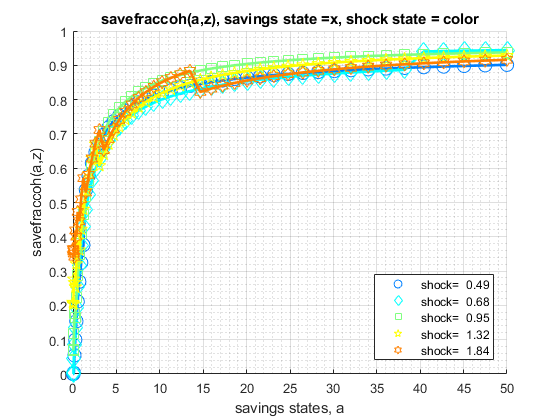

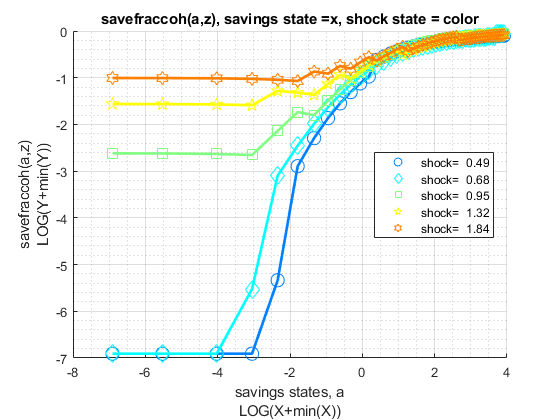

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;
% ls_ffcmd: summary print which outcomes
mp_support('ls_ffcmd') = {};
% ls_ffsna: detail print which outcomes
mp_support('ls_ffsna') = {'savefraccoh'};
% ls_ffgrh: graphical print which outcomes
mp_support('ls_ffgrh') = {'savefraccoh'};
ff_vfi_az_vec(mp_params, mp_support);

Run the function and show summaries for savings and fraction of coh saved:

mp_params('it_a_n') = 100;
mp_params('it_z_n') = 9;
mp_support('ls_ffcmd') = {'ap', 'savefraccoh'};
mp_support('ls_ffsna') = {};
mp_support('ls_ffgrh') = {};
mp_support('bl_vfi_store_all') = true; % store c(a,z), y(a,z)
ff_vfi_az_vec(mp_params, mp_support);

Elapsed time is 0.230510 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean        std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    _______    _______    ________    ___    _______

    ap             1     1      2       900     100      9       12904     14.338     14.524      1.013      0          50
 

## Test FF_VFI_AZ_VEC Change Interest Rate and Discount

Show only save fraction of cash on hand:

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;
mp_support('ls_ffcmd') = {'savefraccoh'};
mp_support('ls_ffsna') = {};
mp_support('ls_ffgrh') = {};
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 100;
mp_params('it_z_n') = 7;
mp_params('fl_a_max') = 50;
mp_params('st_grid_type') = 'grid_powerspace';

Solve the model with several different interest rates and discount factor:

% Lower Savings Incentives
mp_params('fl_beta') = 0.80;
mp_params('fl_r') = 0.01;
ff_vfi_az_vec(mp_params, mp_support);

Elapsed time is 0.058079 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean      std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    ______    ______    ________    ___    _______

    savefraccoh    1     1      2       700     100      7      357.49    0.5107    0.2755    0.53945      0     0.80531

xxx TA

% Higher Savings Incentives
mp_params('fl_beta') = 0.95;
mp_params('fl_r') = 0.04;
ff_vfi_az_vec(mp_params, mp_support);

Elapsed time is 0.177867 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean        std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    _______    _______    ________    ___    _______

    savefraccoh    1     1      2       700     100      7      479.94    0.68563    0.27152    0.39602      0     0.93121



## Test FF_VFI_AZ_VEC Changing Risk Aversion

Here, again, show fraction of coh saved in summary tabular form, but also show it graphically.

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;
mp_support('ls_ffcmd') = {'savefraccoh'};
mp_support('ls_ffsna') = {};
mp_support('ls_ffgrh') = {'savefraccoh'};
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 100;
mp_params('it_z_n') = 7;
mp_params('fl_a_max') = 50;
mp_params('st_grid_type') = 'grid_powerspace';

Solve the model with different risk aversion levels, higher preferences for risk:

Elapsed time is 0.181638 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean       std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    _______    ______    ________    ___    _______

    savefraccoh    1     1      2       700     100      7      450.35    0.64336    0.2803    0.43568      0     0.90711

xxx

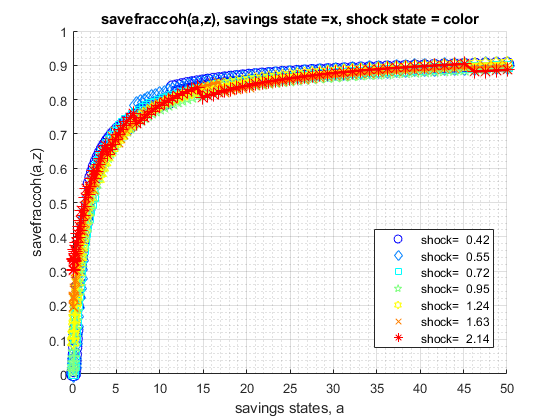

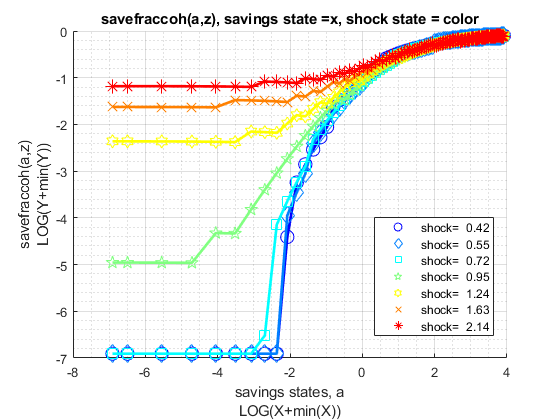

% Lower Risk Aversion
mp_params('fl_crra') = 0.5;
ff_vfi_az_vec(mp_params, mp_support);

When risk aversion increases, at every state-space point, the household wants to save more.

Elapsed time is 0.152901 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean        std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    _______    _______    ________    ___    _______

    savefraccoh    1     1      2       700     100      7      500.59    0.71513    0.25488    0.35641      0     0.94324



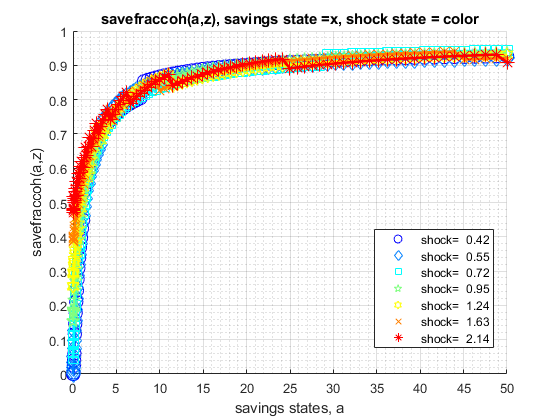

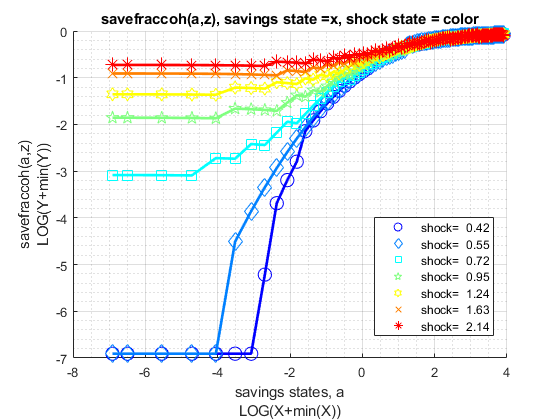

% Higher Risk Aversion
mp_params('fl_crra') = 5;
ff_vfi_az_vec(mp_params, mp_support);

## Test FF_VFI_AZ_VEC with Higher Uncertainty

Increase the standard deviation of the Shock. 

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;
mp_support('ls_ffcmd') = {'savefraccoh'};
mp_support('ls_ffsna') = {};
mp_support('ls_ffgrh') = {};
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 150;
mp_params('it_z_n') = 15;
mp_params('fl_a_max') = 50;
mp_params('st_grid_type') = 'grid_powerspace';
% graph color spectrum
mp_params('cl_colors') = 'copper';

Lower standard deviation of shock:

% Lower Risk Aversion
mp_params('fl_shk_std') = 0.10;
ff_vfi_az_vec(mp_params, mp_support);

Elapsed time is 0.544499 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean        std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    _______    _______    ________    ___    _______

    savefraccoh    1     1      2      2250     150      15     1506.3    0.66947    0.28673     0.4283      0     0.93222



Higher shock standard deviation: low shock high asset save more, high shock more asset save less, high shock low asset save more:

% Higher Risk Aversion
mp_params('fl_shk_std') = 0.40;
ff_vfi_az_vec(mp_params, mp_support);

Elapsed time is 0.515060 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean        std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    _______    _______    ________    ___    _______

    savefraccoh    1     1      2      2250     150      15     1678.8    0.74614    0.22779    0.30529      0     0.93141

